map =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


map =      1     1     1     1     1     0     1     1     1     1
     1     1     1     1     1     0     1     1     1     1
     1     1     1     1     1     0     1     1     1     1
     1     1     1     1     1     0     1     1     1     1
     1     1     1     1     1     0     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1


map =      1     1     1     1     1     2     1     1     1     1
     1     1     1     1     1     2     1     1     1     1
     1     1     1     1     1     2     1     1     1     1
     1     1     1     1     1     2     1     1     1     1
     1     1     1     1     1     2     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1


start_node = 16

dest_node = 88

distanceFromStart =    Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf


parent =      2    12    11    21    31     0    62     0     0     0
     3    13    12    22    32     0    63    62     0     0
     4    14    13    23    33     0    64    63    73     0
     5    15    14    24    34     0    65    64    74    84
     6    16    15    25    35     0    66    65    75    85
    16     0    16    26    36    46    56    66    76    86
     6    16    17    27    37    47    57    67    77    87
     7    17    18    28    38    48    58    68    87     0
     8    18    19    29    39    49    59    69    79     0
     9    19    20    30    40    50    60    70     0     0


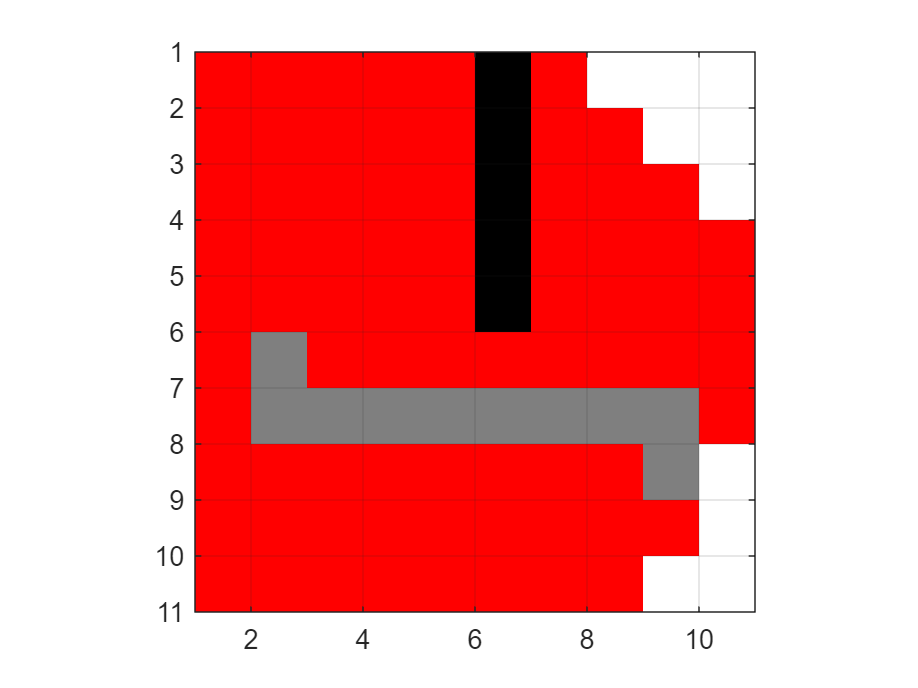


%% Define a small map
map = false(10);
% Add an obstacle
map (1:5, 6) = true;

start_coords = [6, 2];
dest_coords  = [8, 9];

%%
close all;
[route, numExpanded] = DijkstraGrid (map, start_coords, dest_coords);


%HINT: With default start and destination coordinates defined above, numExpanded for Dijkstras should be 76, numExpanded for Astar should be 23.


function [route,numExpanded] = DijkstraGrid (input_map, start_coords, dest_coords)
% Run Dijkstra's algorithm on a grid.
% Inputs : 
%   input_map : a logical array where the freespace cells are false or 0 and the obstacles are true or 1
%   start_coords and dest_coords : Coordinates of the start and end cell
%   respectively, the first entry is the row and the second the column.
% Output :
%    route : An array containing the linear indices of the cells along the
%    shortest route from start to dest or an empty array if there is no
%    route. This is a single dimensional vector
%    numExpanded: Remember to also return the total number of nodes
%    expanded during your search. Do not count the goal node as an expanded node.


% set up color map for display
% 1 - white - clear cell
% 2 - black - obstacle
% 3 - red = visited
% 4 - blue  - on list
% 5 - green - start
% 6 - yellow - destination

cmap = [1 1 1; ...
        0 0 0; ...
        1 0 0; ...
        0 0 1; ...
        0 1 0; ...
        1 1 0; ...
    0.5 0.5 0.5];

colormap(cmap);

% variable to control if the map is being visualized on every
% iteration
drawMapEveryTime = true;

[nrows, ncols] = size(input_map);

% map - a table that keeps track of the state of each grid cell
map = zeros(nrows,ncols)

map(~input_map) = 1   % Mark free cells
map(input_map)  = 2   % Mark obstacle cells

% Generate linear indices of start and dest nodes
%ind = sub2ind(sz,row,col) 针对大小为 sz 的矩阵返回由 row 和 col 指定的行列下标的对应线性索引 ind。
% 此处，sz 是包含两个元素的向量，其中 sz(1) 指定行数，sz(2) 指定列数。
start_node = sub2ind(size(map), start_coords(1), start_coords(2))%线性索引
dest_node  = sub2ind(size(map), dest_coords(1),  dest_coords(2))%线性索引

map(start_node) = 5;
map(dest_node)  = 6;

% Initialize distance array
distanceFromStart = Inf(nrows,ncols)

% For each grid cell this array holds the index of its parent
parent = zeros(nrows,ncols);

distanceFromStart(start_node) = 0;

% keep track of number of nodes expanded 
numExpanded = 0;

% Main Loop
while true
    
    % Draw current map
    map(start_node) = 5;
    map(dest_node) = 6;
    
    % make drawMapEveryTime = true if you want to see how the 
    % nodes are expanded on the grid. 
    if (drawMapEveryTime)
        image(1.5, 1.5, map);%从数组显示图像
        grid on;
        axis image;
        drawnow;
    end
    
    % Find the node with the minimum distance
    %distanceFromStart(:)
    %current 目前探索的节点
    [min_dist, current] = min(distanceFromStart(:));
    
    if ((current == dest_node) || isinf(min_dist))
        break;
    end;
    
    % Update map
    map(current) = 3;         % mark current node as visited
    distanceFromStart(current) = Inf; % remove this node from further consideration
    
    % Compute row, column coordinates of current node
    [i, j] = ind2sub(size(distanceFromStart), current);
    
    
    % Visit each neighbor of the current node and update the map, distances
    % and parent tables appropriately.
    numExpanded = numExpanded + 1; %运行一次就有一次增加了
    current_node=[i,j];%i是row j是col
    south_node=[i+1,j];
    north_node=[i-1,j];
    east_node=[i,j+1];
    west_node=[i,j-1];
    neighbourhood=[south_node;north_node;east_node;west_node];
    for k=1:4
        %第一组邻居开始查找确保 有邻居且没有出边界
        if( (neighbourhood(k,1)>0 && neighbourhood(k,2)>0) && (neighbourhood(k,1)<=nrows && neighbourhood(k,2)<=ncols))
            %此邻居没有被访问过，不是障碍物，也不是起点
            if( map(neighbourhood(k,1),neighbourhood(k,2)) ~=3 && map(neighbourhood(k,1),neighbourhood(k,2)) ~=2 && map(neighbourhood(k,1),neighbourhood(k,2)) ~=5 || map(neighbourhood(k,1),neighbourhood(k,2)) == 6)
                %距离比以前存下来的距离更近
                if(distanceFromStart(neighbourhood(k,1),neighbourhood(k,2)) >  1+sum(abs(start_coords-current_node)) || map(neighbourhood(k,1),neighbourhood(k,2)) == 6)
                    map(neighbourhood(k,1),neighbourhood(k,2))=4;%先进入现在探索列表中
                    distanceFromStart(neighbourhood(k,1),neighbourhood(k,2))=1+sum(abs(start_coords-current_node));
                    parent(neighbourhood(k,1),neighbourhood(k,2))=sub2ind(size(map),current);%把现在的邻居点加入到父列表中
                    map(neighbourhood(k,1),neighbourhood(k,2))=3;%放入已经访问的标识符
                end
            end
        end
    end
    %*********************************************************************
    
end
parent
%% Construct route from start to dest by following the parent links
if (isinf(distanceFromStart(dest_node)))
    route = [];
else
    route = [dest_node];
    
    while (parent(route(1)) ~= 0)
        route = [parent(route(1)), route];
    end
    
        % Snippet of code used to visualize the map and the path
    for k = 1:length(route)        
        map(route(k)) = 7;
        pause(0.1);
        image(1.5, 1.5, map);
        grid on;
        axis image;
    end
end

end
